clc; clear all; close all;
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
Quemados_Brightest_image_path = fullfile('Pruebas_Quemados','Quemados','Quemados_Brightest_1405_9_images');
Quemados_Correlated_image_path = fullfile('Pruebas_Quemados','Quemados','Quemados_Correlated_1405_9_images');
NOQuemados_Brightest_image_path = fullfile('Pruebas_Quemados','NOQuemados','NOQuemados_Brightest_1405_9_images');
NOQuemados_Correlated_image_path = fullfile('Pruebas_Quemados','NOQuemados','NOQuemados_Correlated_1405_9_images');
load('meanHistRGB9.mat');%esto te da la variable MeanHistRGB
vignette=double(rgb2gray(imread('viñeta2.jpg')));
vignette=vignette./max(vignette(:));

factor_reduccion = 1/10; 
dimensiones_nuevas = [2425, 3005];%Para que todas las imagenes entren al for con el mismo tamaño
margen=300/10;%este es el tamaño de las ventanas que se van a usar, tiene que coincidir con el tamaño de las plantillas

tR=0.5;
tG=2;
tB=1;

margen_zoom=430;
se = strel('disk',100);

%indices = find(T.quality == 4);

k = 1

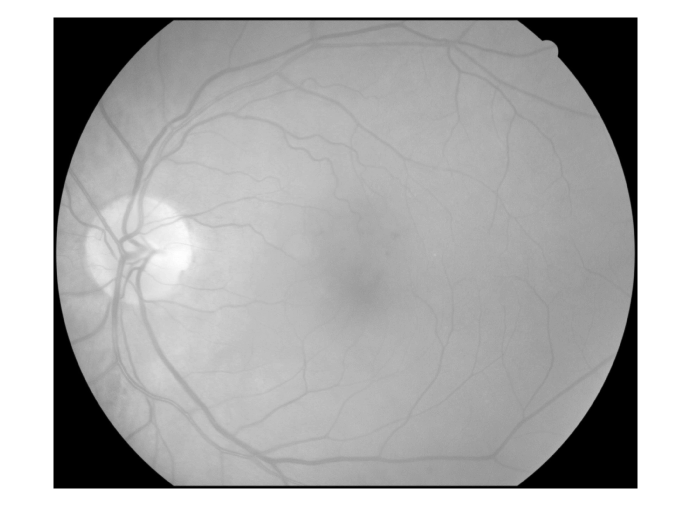

Error using imwrite (line 549)
Unable to open file "Pruebas_Quemados\Quemados\Quemados_Brightest_1405_9_images\image_0001.jpg" for writing. Check write permission.

for u = 1:height(T)
    k=u

% Leer la imagen original
RGB = imread(string(fullfile(img_path, T{k,1})));

% Le paso un filtro para quitarle el ruido
RGB(:,:,1)=medfilt2(RGB(:,:,1),[3 3],"symmetric");
RGB(:,:,2)=medfilt2(RGB(:,:,2),[3 3],"symmetric");
RGB(:,:,3)=medfilt2(RGB(:,:,3),[3 3],"symmetric");


RGB_sinQuemado=uint8(RGB);
RGB=uint8(RGB);


[alto_original, ancho_original, ~] = size(RGB_sinQuemado);
imagen_redimensionada = imresize(RGB_sinQuemado, dimensiones_nuevas);
new_size = [size(imagen_redimensionada, 1) * factor_reduccion, size(imagen_redimensionada, 2) * factor_reduccion];
RGBa = imresize(imagen_redimensionada, new_size, 'bicubic');

[alto, ancho, ~] = size(RGBa);
CM=zeros(alto-margen*2,ancho-margen*2);
diff=zeros(alto-margen*2,ancho-margen*2);
dif=zeros(alto-margen*2,ancho-margen*2,3);

for i=1:3
    for x=margen+1:ancho-margen
        for y=margen+1:alto-margen
            layer_zoom=RGBa(y-margen:y+margen, x-margen:x+margen, i);
            [hist_layer, ~] = imhist(layer_zoom);
            diff(y-margen,x-margen)=sum(bsxfun(@minus, hist_layer, meanHistRGB(i)).^2);
        end
        
    end
    dif(:,:,i)=diff;
end

c=1/(1+dif);
CM = c(:,:,1).*tR + c(:,:,2).*tG + c(:,:,3);
CM_padded = padarray(CM, [margen margen], 0);%como no se ha puesto un margen, ahora hay que hacerle un padding pa sumárselo
CM_padded_redimensioned = imresize(CM_padded, [alto_original ancho_original]);
thres=CM_padded_redimensioned>0.93*max(CM_padded_redimensioned(:));


[media_izquierda, media_derecha]=medias(RGB, se);


Ig=rgb2gray(RGB);
imshow(Ig,[]);
thresh1=Ig>0.7*max(Ig(:));
thresh1=uint8(thresh1);

thresh=CM_padded_redimensioned>0.7*max(CM_padded_redimensioned(:));
thresh=uint8(thresh);

 if (media_derecha > 100) || (media_izquierda > 100)

     nombre_archivo1 = cell2mat(fullfile(Quemados_Brightest_image_path, T{k,1})); 
     imwrite(thresh1, nombre_archivo1);

     nombre_archivo2 = cell2mat(fullfile(Quemados_Correlated_image_path, T{k,1})); 
     imwrite(thresh, nombre_archivo2);

 else
     nombre_archivo1 = cell2mat(fullfile(NOQuemados_Brightest_image_path, T{k,1})); 
     imwrite(thresh1, nombre_archivo1);

     nombre_archivo2 = cell2mat(fullfile(NOQuemados_Correlated_image_path, T{k,1})); 
     imwrite(thresh, nombre_archivo2);

 end


end